%% FARO 21000 General DH Error Propagation Model
% Based on Hall & Schreve error propagation model:
%
%       Lambda_F = J * Lambda_theta * J'
%
% Purpose:
% - Model the FaroArm Quantum 21000, size 3000 mm
% - Compute uncertainty over many poses
% - Allow any joint to be swept or locked
% - Allow the code to work for any number of DH links
% - Extract uncertainty metrics for TPM derivation
%
% Units:
% - Lengths in mm
% - Angles in radians internally
% - Encoder standard deviation in radians internally
%
% Important:
% - This script no longer computes only one single pose.
% - The whole model is now driven by the theta_lists_deg cell array.
% - A scalar locks a joint.
% - A vector sweeps a joint.

# Define DH model

This section defines the geoetry of the arm. The vectors a, d, and alpha describe how each joint frame is positioned relative to the previous one.

- The validation code checks that all DH parameter vectors have the same length. This prevents the model from trying to compute a 6-joint arm with only 5 twist angles, for example.

clear; clc; close all;

%% 1. Define DH model

% FaroArm Quantum 21000, size 3000 mm
L1 = 755;   % mm
L2 = 569;   % mm

% Simplified DH geometry for the 3000 mm arm
% a_i are set to zero because perpendicular joint-axis offsets are not
% included in this simplified geometric approximation.
a = [0 0 0 0 0 0];

% d_i contains the visible base, arm, forearm, and probe dimensions
d = [283 L1 0 L2 0 220];

% Twist angles
% Recommended nominal option when following Hall & Schreve's AACMM DH pattern:
alpha_deg = [90 -90 90 -90 -90 180];

% If you want to test your earlier simplified assumed twist sequence, use:
% alpha_deg = [90 -90 90 -90 90 0];

alpha = deg2rad(alpha_deg);

% Number of DH links / joints
n = numel(a);

% Basic validation
if numel(d) ~= n || numel(alpha) ~= n
    error('DH parameter vectors a, d, and alpha must have the same length.');
end

fprintf('\n--- DH model definition ---\n');


--- DH model definition ---


fprintf('Number of DH links / joints: %d\n', n);

Number of DH links / joints: 6



DH_table = table((1:n).', a(:), alpha_deg(:), d(:), ...
    'VariableNames', {'Link','a_mm','alpha_deg','d_mm'});

disp(DH_table);

    Link    a_mm    alpha_deg    d_mm
    ____    ____    _________    ____

     1       0          90       283 
     2       0         -90       755 
     3       0          90         0 
     4       0         -90       569 
     5       0         -90         0 
     6       0         180       220 



# Define Encoder Covariance

This section defines the uncertainty in the input joint angles. The model assumes each encoder angle has a small deviation.

Lambda_theta is the encoder covariance matrix. It assumes:

- All joints have the same variance

- The encoder errors are independent

- There is no covarience between different encoders


$$\Lambda_{\theta } ={\sigma_{\theta } }^2 I$$


This is the input uncertainty that later gets propagated to the probe tip.

%% 2. Define encoder covariance

% Nominal encoder standard deviation
% This value is a scaling assumption. It should later be calibrated using
% SPAT, repeatability, or experimental FaroArm data.
sigma_theta_arcsec = 6;
sigma_theta = arcsec2rad_local(sigma_theta_arcsec);

% Independent equal-variance encoder covariance matrix
Lambda_theta = (sigma_theta^2) * eye(n);

fprintf('\n--- Encoder covariance ---\n');


--- Encoder covariance ---


fprintf('Assumed encoder standard deviation = %.3f arc-sec\n', sigma_theta_arcsec);

Assumed encoder standard deviation = 6.000 arc-sec


fprintf('Assumed encoder standard deviation = %.6e rad\n', sigma_theta);

Assumed encoder standard deviation = 2.908882e-05 rad


# Define Joint Sweep / Locked-Joint Configuration

This section defines which pose the model will evaluate. 

The strategy is choose joint angles that represent a subset of the arm's usable workspace sufficient enough to capture uncertainty trends within the sample case:

- The goal is analyse the trend of uncertainty in the arm, not to replicate the physical limits of the arm

- The error propagation model is pose-dependent, so sampling is required.

- Uniform sampling allows for: Comparison between poses, identification of worst-case behaviour

- Extreme configuration are excluded to avoid singularities and maintain validity of the first-order approximation 

%% 3. Define joint sweep / locked-joint configuration

% Each cell represents one joint.
% Each cell define the set of arm configurations (poses) at which the
% uncertainty model is evaluated.
% Each entry corresponds to one joint:
% ~ A vector -> joint is swept
% ~ A scalar -> joint is locked (0)

theta_lists_deg = {
    ... theta1: base rotation
    ... Base rotation sweeps from left to right across the workspace
    linspace(-90, 90, 13),
    ... theta2: shoulder
    ... Shoulder operates within a mid-range motion band
    linspace(10, 80, 10),
    ... theta3: elbow
    ... Elbow allows extension and contraction of the arm
    linspace(-60, 60, 10),  
    ... theta4: wrist
    ... Wrist joints vary within a smaller angular range
    linspace(-45, 45, 7),
    ... theta5: wrist
    linspace(-45, 45, 7),
    ... theta6: wrist / probe roll
    linspace(-45, 45, 7)       
};

% Example: to lock a joint, replace its list with a scalar:
% theta_lists_deg{4} = 0;      % lock theta4
% theta_lists_deg{5} = 0;      % lock theta5
% theta_lists_deg{6} = 0;      % lock theta6

if numel(theta_lists_deg) ~= n
    error('Number of theta lists must match the number of DH links.');
end

% Count poses and identify locked / swept joints
N = 1;
is_locked = false(1,n);

for i = 1:n
    N = N * numel(theta_lists_deg{i});

    if numel(theta_lists_deg{i}) == 1
        is_locked(i) = true;
    end
end

fprintf('\n--- Joint sampling setup ---\n');


--- Joint sampling setup ---


fprintf('Total number of poses to evaluate: %d\n', N);

Total number of poses to evaluate: 445900



for i = 1:n
    if is_locked(i)
        fprintf('theta%d locked at %.3f deg\n', i, theta_lists_deg{i});
    else
        fprintf('theta%d swept from %.3f deg to %.3f deg using %d values\n', ...
            i, min(theta_lists_deg{i}), max(theta_lists_deg{i}), numel(theta_lists_deg{i}));
    end
end

theta1 swept from -90.000 deg to 90.000 deg using 13 values
theta2 swept from 10.000 deg to 80.000 deg using 10 values
theta3 swept from -60.000 deg to 60.000 deg using 10 values
theta4 swept from -45.000 deg to 45.000 deg using 7 values
theta5 swept from -45.000 deg to 45.000 deg using 7 values
theta6 swept from -45.000 deg to 45.000 deg using 7 values


%% 4. Preallocate result arrays

% Store pose coordinates and uncertainty metrics
XYZ = zeros(N,3);
reach_vals = zeros(N,1);

U95_vals = zeros(N,1);
u_max_vals = zeros(N,1);

sigma1_vals = zeros(N,1);
sigma2_vals = zeros(N,1);
sigma3_vals = zeros(N,1);

sigmaR_vals = zeros(N,1);
sigmaT_vals = zeros(N,1);
sigmaZ_vals = zeros(N,1);

anisotropy_vals = zeros(N,1);

% Set this to false if N is very large and you want to save memory.
% If false, the code still stores the best/worst poses separately.
STORE_ALL_ANGLES = true;

if STORE_ALL_ANGLES
    theta_deg_all = zeros(N,n);
else
    theta_deg_all = [];
end


# Evaluate Uncertainty Over All Generated Poses

This computes

- Forward kinematics

- Jacobian matrix

- Propagated covariance

- Uncertainty axes

- Radial / tangential / vertical uncertainties

- Anisotrophy

The outputs are then stored. The code also evaluates best and worst case scenarios:

- Best case:

- ~ The Jacobian is "well-conditioned"

- ~ The arm is most precise

- ~ Characteristics: Compact posture, balanced geometry, lower sensitivity to joint errors

- Worst case:

- ~ the Jacobian amplifies encoder errors the most

- ~ The am is least precise

- ~ Characteristics: Large reach, poor geometry, high anisotrophy

%% 5. Evaluate uncertainty over all generated poses

fprintf('\n--- Evaluating poses ---\n');


--- Evaluating poses ---



% Length of each joint list
list_lengths = zeros(1,n);
for i = 1:n
    list_lengths(i) = numel(theta_lists_deg{i});
end

% Variables for best/worst tracking
maxU95 = -inf;
minU95 = inf;

worst_pose_deg = zeros(1,n);
best_pose_deg = zeros(1,n);

worst_position = zeros(3,1);
best_position = zeros(3,1);

for idx = 1:N

    % Convert linear index into subscript indices for each joint list
    subs = cell(1,n);
    [subs{:}] = ind2sub(list_lengths, idx);

    % Build joint vector for this pose
    theta_deg_i = zeros(1,n);

    for j = 1:n
        theta_deg_i(j) = theta_lists_deg{j}(subs{j});
    end

    theta_i = deg2rad(theta_deg_i);

    % Evaluate uncertainty at this pose
    result_i = evaluate_pose_uncertainty(theta_i, alpha, a, d, Lambda_theta);

    % Store main results
    XYZ(idx,:) = result_i.p.';
    reach_vals(idx) = norm(result_i.p);

    U95_vals(idx) = result_i.U95;
    u_max_vals(idx) = result_i.sigma_axes(1);

    sigma1_vals(idx) = result_i.sigma_axes(1);
    sigma2_vals(idx) = result_i.sigma_axes(2);
    sigma3_vals(idx) = result_i.sigma_axes(3);

    sigmaR_vals(idx) = result_i.sigmaR;
    sigmaT_vals(idx) = result_i.sigmaT;
    sigmaZ_vals(idx) = result_i.sigmaZ;

    anisotropy_vals(idx) = result_i.anisotropy;

    if STORE_ALL_ANGLES
        theta_deg_all(idx,:) = theta_deg_i;
    end

    % Track worst and best poses without needing to store every angle
    if result_i.U95 > maxU95
        maxU95 = result_i.U95;
        worst_pose_deg = theta_deg_i;
        worst_position = result_i.p;
    end

    if result_i.U95 < minU95
        minU95 = result_i.U95;
        best_pose_deg = theta_deg_i;
        best_position = result_i.p;
    end

    % Progress update
    if mod(idx, max(1, floor(N/10))) == 0
        fprintf('Progress: %.0f %%\n', 100*idx/N);
    end
end

Progress: 10 %
Progress: 20 %
Progress: 30 %
Progress: 40 %
Progress: 50 %
Progress: 60 %
Progress: 70 %
Progress: 80 %
Progress: 90 %
Progress: 100 %



fprintf('Pose evaluation complete.\n');

Pose evaluation complete.


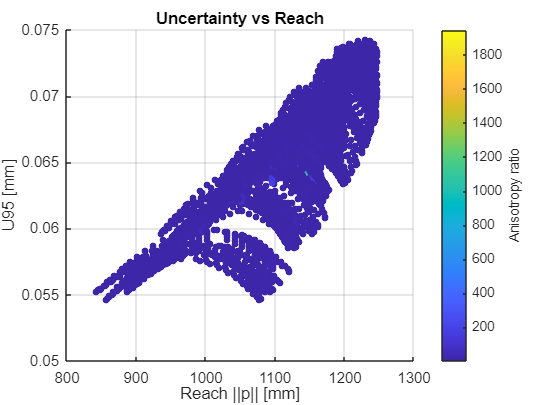

%% 6. Uncertainty plots

% Plot 1: U95 vs reach
figure;
scatter(reach_vals, U95_vals, 20, anisotropy_vals, 'filled');
xlabel('Reach ||p|| [mm]');
ylabel('U95 [mm]');
title('Uncertainty vs Reach');
cb = colorbar;
cb.Label.String = 'Anisotropy ratio';
grid on;

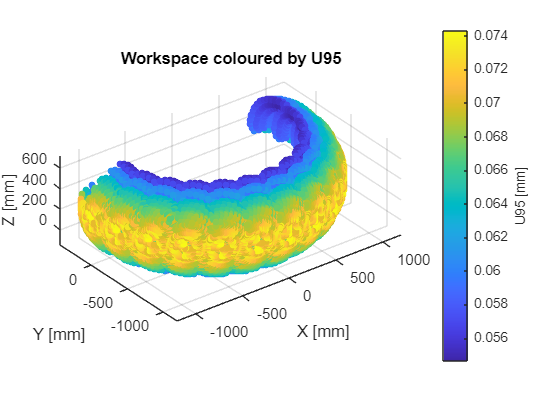


% Plot 2: workspace coloured by U95
figure;
scatter3(XYZ(:,1), XYZ(:,2), XYZ(:,3), 20, U95_vals, 'filled');
xlabel('X [mm]');
ylabel('Y [mm]');
zlabel('Z [mm]');
title('Workspace coloured by U95');
cb = colorbar;
cb.Label.String = 'U95 [mm]';
grid on;
axis equal;

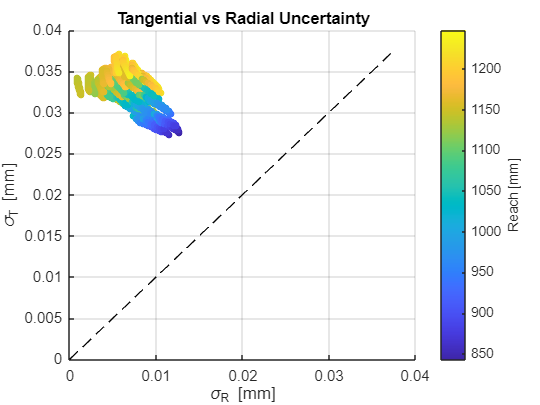


% Plot 3: tangential vs radial uncertainty
figure;
scatter(sigmaR_vals, sigmaT_vals, 20, reach_vals, 'filled');
xlabel('\sigma_R [mm]');
ylabel('\sigma_T [mm]');
title('Tangential vs Radial Uncertainty');
cb = colorbar;
cb.Label.String = 'Reach [mm]';
grid on;
hold on;
mx = max([sigmaR_vals; sigmaT_vals]);
plot([0 mx], [0 mx], '--k');
hold off;

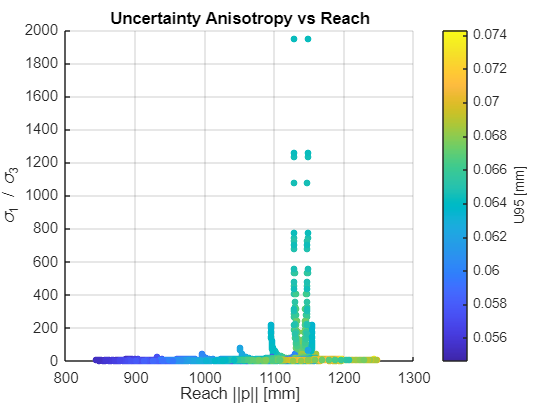


% Plot 4: anisotropy vs reach
figure;
scatter(reach_vals, anisotropy_vals, 20, U95_vals, 'filled');
xlabel('Reach ||p|| [mm]');
ylabel('\sigma_1 / \sigma_3');
title('Uncertainty Anisotropy vs Reach');
cb = colorbar;
cb.Label.String = 'U95 [mm]';
grid on;

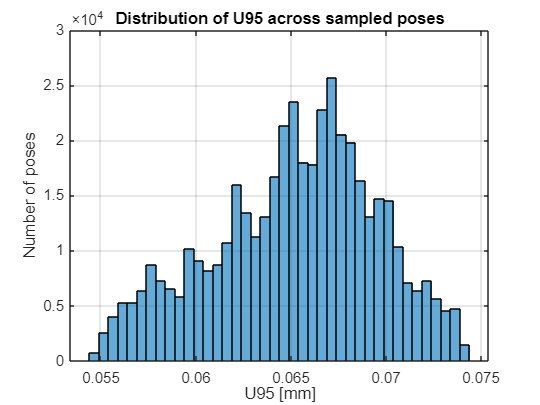


% Plot 5: histogram of U95
figure;
histogram(U95_vals, 40);
xlabel('U95 [mm]');
ylabel('Number of poses');
title('Distribution of U95 across sampled poses');
grid on;

%% 7. Summary metrics for TPM derivation

meanU95 = mean(U95_vals);
medianU95 = median(U95_vals);
stdU95 = std(U95_vals);

meanSigmaR = mean(sigmaR_vals);
meanSigmaT = mean(sigmaT_vals);
meanSigmaZ = mean(sigmaZ_vals);

meanTangentialRadialRatio = mean(sigmaT_vals ./ max(sigmaR_vals, eps));
maxAnisotropy = max(anisotropy_vals);
meanAnisotropy = mean(anisotropy_vals);

fprintf('\n--- Workspace uncertainty summary ---\n');


--- Workspace uncertainty summary ---


fprintf('Mean U95   = %.6f mm\n', meanU95);

Mean U95   = 0.065203 mm


fprintf('Median U95 = %.6f mm\n', medianU95);

Median U95 = 0.065606 mm


fprintf('Std U95    = %.6f mm\n', stdU95);

Std U95    = 0.004325 mm


fprintf('Max U95    = %.6f mm\n', maxU95);

Max U95    = 0.074302 mm


fprintf('Min U95    = %.6f mm\n', minU95);

Min U95    = 0.054647 mm



fprintf('\nWorst-case pose [deg]: [%s]\n', num2str(worst_pose_deg));


Worst-case pose [deg]: [-45  10  20   0  45 -45]


fprintf('Worst-case position [mm]: [%.3f %.3f %.3f]\n', ...
    worst_position(1), worst_position(2), worst_position(3));

Worst-case position [mm]: [-849.529 -842.874 282.170]



fprintf('\nBest-case pose [deg]: [%s]\n', num2str(best_pose_deg));


Best-case pose [deg]: [-90  80 -60   0  30 -45]


fprintf('Best-case position [mm]: [%.3f %.3f %.3f]\n', ...
    best_position(1), best_position(2), best_position(3));

Best-case position [mm]: [-848.974 66.467 -93.953]



fprintf('\n--- Directional uncertainty summary ---\n');


--- Directional uncertainty summary ---


fprintf('Mean sigma_R = %.6f mm\n', meanSigmaR);

Mean sigma_R = 0.006655 mm


fprintf('Mean sigma_T = %.6f mm\n', meanSigmaT);

Mean sigma_T = 0.032564 mm


fprintf('Mean sigma_Z = %.6f mm\n', meanSigmaZ);

Mean sigma_Z = 0.008912 mm


fprintf('Mean tangential/radial ratio = %.3f\n', meanTangentialRadialRatio);

Mean tangential/radial ratio = 6.337



fprintf('\n--- Anisotropy summary ---\n');


--- Anisotropy summary ---


fprintf('Mean anisotropy ratio = %.3f\n', meanAnisotropy);

Mean anisotropy ratio = 18.311


fprintf('Max anisotropy ratio  = %.3f\n', maxAnisotropy);

Max anisotropy ratio  = 1945.943



fprintf('\n--- Candidate TPMs from current model ---\n');


--- Candidate TPMs from current model ---


fprintf('TPM 1: Worst-case U95 over sampled poses = %.6f mm\n', maxU95);

TPM 1: Worst-case U95 over sampled poses = 0.074302 mm


fprintf('TPM 2: Mean U95 over sampled poses       = %.6f mm\n', meanU95);

TPM 2: Mean U95 over sampled poses       = 0.065203 mm


fprintf('TPM 3: Median U95 over sampled poses     = %.6f mm\n', medianU95);

TPM 3: Median U95 over sampled poses     = 0.065606 mm


fprintf('TPM 4: Mean tangential/radial ratio      = %.3f\n', meanTangentialRadialRatio);

TPM 4: Mean tangential/radial ratio      = 6.337


fprintf('TPM 5: Maximum anisotropy ratio          = %.3f\n', maxAnisotropy);

TPM 5: Maximum anisotropy ratio          = 1945.943


%% 8. Optional: save results to file

SAVE_RESULTS = true;

if SAVE_RESULTS
    if STORE_ALL_ANGLES
        results_table = array2table(theta_deg_all, ...
            'VariableNames', compose('theta%d_deg', 1:n));
    else
        results_table = table();
    end

    results_table.X_mm = XYZ(:,1);
    results_table.Y_mm = XYZ(:,2);
    results_table.Z_mm = XYZ(:,3);
    results_table.Reach_mm = reach_vals;
    results_table.U95_mm = U95_vals;
    results_table.sigma1_mm = sigma1_vals;
    results_table.sigma2_mm = sigma2_vals;
    results_table.sigma3_mm = sigma3_vals;
    results_table.sigmaR_mm = sigmaR_vals;
    results_table.sigmaT_mm = sigmaT_vals;
    results_table.sigmaZ_mm = sigmaZ_vals;
    results_table.Anisotropy = anisotropy_vals;

    writetable(results_table, 'FaroArm_uncertainty_results.csv');

    fprintf('\nResults saved to FaroArm_uncertainty_results.csv\n');
end


Results saved to FaroArm_uncertainty_results.csv



%% Local functions

function result = evaluate_pose_uncertainty(theta, alpha, a, d, Lambda_theta)

    % Forward kinematics
    [T06, A_all] = forward_kinematics_local(theta, alpha, a, d);
    p = T06(1:3,4);

    % Jacobian
    J = compute_jacobian_dh_local(theta, alpha, a, d, A_all);

    % Error propagation
    Lambda_F = J * Lambda_theta * J.';
    Lambda_F = 0.5 * (Lambda_F + Lambda_F.');

    % Principal uncertainties
    [V, D] = eig(Lambda_F);
    eigvals = diag(D);
    [eigvals, idx] = sort(real(eigvals), 'descend');
    V = V(:, idx);

    eigvals(eigvals < 0) = 0;
    sigma_axes = sqrt(eigvals);

    % Radial / tangential / vertical directions
    r_xy = norm(p(1:2));

    if r_xy > 1e-12
        eR = [p(1); p(2); 0] / r_xy;
        eT = [-p(2); p(1); 0] / r_xy;
    else
        eR = [1;0;0];
        eT = [0;1;0];
    end

    eZ = [0;0;1];

    sigmaR = sqrt(max(eR.' * Lambda_F * eR, 0));
    sigmaT = sqrt(max(eT.' * Lambda_F * eT, 0));
    sigmaZ = sqrt(max(eZ.' * Lambda_F * eZ, 0));

    % Store outputs
    result.T06 = T06;
    result.p = p;
    result.J = J;
    result.Lambda_F = Lambda_F;
    result.V = V;
    result.sigma_axes = sigma_axes;
    result.U95 = 2 * sigma_axes(1);
    result.sigmaR = sigmaR;
    result.sigmaT = sigmaT;
    result.sigmaZ = sigmaZ;
    result.anisotropy = sigma_axes(1) / max(sigma_axes(3), eps);

end


%% 8. TPM value derivation

% -------------------------------
% User-selected spatial target
% -------------------------------
% Choose based on ISO-style MPE, manufacturer SPAT, or project requirement.
U95_target = 0.050;   % mm, example target = 50 microns

% Back-calculate required encoder accuracy from current model
sigma_theta_required = sigma_theta * (U95_target / maxU95);
sigma_theta_required_arcsec = sigma_theta_required * (180 * 3600) / pi;
encoder_counts_required = 2*pi / sigma_theta_required;

% TPM_30 Encoder accuracy
TPM_30_encoder_accuracy_rad = sigma_theta_required;
TPM_30_encoder_accuracy_arcsec = sigma_theta_required_arcsec;

% TPM_40 Spatial accuracy
TPM_40_spatial_accuracy_model = maxU95;

% TPM_70 Repeatability
TPM_70_repeatability_worst = maxU95;
TPM_70_repeatability_typical = medianU95;

% TPM_20 Run-out tolerance
joint_radius = 20;   % mm, replace with design radius
TPM_20_runout_max_mm = joint_radius * sigma_theta_required;

% TPM_10 Holding torque
m_distal = 1.5;      % kg, replace with CAD/mass estimate
L_CoM = 0.35;        % m, replace with CoM distance
g = 9.81;
SF_torque = 1.5;

tau_gravity = m_distal * g * L_CoM;
TPM_10_holding_torque_Nm = SF_torque * tau_gravity;

% TPM_60 Joint stiffness
tau_max_joint = TPM_10_holding_torque_Nm;
TPM_60_joint_stiffness_Nm_per_rad = tau_max_joint / sigma_theta_required;

% TPM_50 Joint lifecycle
TPM_50_lifecycle_cycles = 10000;          % choose based on project scope
TPM_50_max_torque_degradation = 0.10;     % 10 %

% TPM_80 Joint mass
TPM_80_joint_mass_max_kg = 0.50;          % choose from mass budget

fprintf('\n================ TPM VALUES ================\n');


================ TPM VALUES ================



fprintf('\nTPM_10 Holding torque\n');


TPM_10 Holding torque


fprintf('Required holding torque = %.3f Nm\n', TPM_10_holding_torque_Nm);

Required holding torque = 7.725 Nm



fprintf('\nTPM_20 Run-out tolerance\n');


TPM_20 Run-out tolerance


fprintf('Maximum allowable run-out = %.6f mm = %.3f microns\n', ...
    TPM_20_runout_max_mm, TPM_20_runout_max_mm*1000);

Maximum allowable run-out = 0.000391 mm = 0.391 microns



fprintf('\nTPM_30 Encoder accuracy\n');


TPM_30 Encoder accuracy


fprintf('Required encoder std dev = %.6e rad = %.3f arc-sec\n', ...
    TPM_30_encoder_accuracy_rad, TPM_30_encoder_accuracy_arcsec);

Required encoder std dev = 1.957485e-05 rad = 4.038 arc-sec


fprintf('Equivalent minimum counts/rev = %.0f\n', encoder_counts_required);

Equivalent minimum counts/rev = 320983



fprintf('\nTPM_40 Spatial accuracy\n');


TPM_40 Spatial accuracy


fprintf('Model-predicted worst-case U95 = %.6f mm\n', TPM_40_spatial_accuracy_model);

Model-predicted worst-case U95 = 0.074302 mm


fprintf('Target U95 used for derivation = %.6f mm\n', U95_target);

Target U95 used for derivation = 0.050000 mm



fprintf('\nTPM_50 Joint lifecycle\n');


TPM_50 Joint lifecycle


fprintf('Required lifecycle = %d cycles\n', TPM_50_lifecycle_cycles);

Required lifecycle = 10000 cycles


fprintf('Maximum torque degradation = %.1f %%\n', TPM_50_max_torque_degradation*100);

Maximum torque degradation = 10.0 %



fprintf('\nTPM_60 Joint stiffness\n');


TPM_60 Joint stiffness


fprintf('Minimum rotational stiffness = %.3e Nm/rad\n', TPM_60_joint_stiffness_Nm_per_rad);

Minimum rotational stiffness = 3.947e+05 Nm/rad



fprintf('\nTPM_70 Repeatability\n');


TPM_70 Repeatability


fprintf('Worst-case repeatability indicator U95 = %.6f mm\n', TPM_70_repeatability_worst);

Worst-case repeatability indicator U95 = 0.074302 mm


fprintf('Typical repeatability indicator median U95 = %.6f mm\n', TPM_70_repeatability_typical);

Typical repeatability indicator median U95 = 0.065606 mm



fprintf('\nTPM_80 Joint mass\n');


TPM_80 Joint mass


fprintf('Maximum allowable joint mass = %.3f kg\n', TPM_80_joint_mass_max_kg);

Maximum allowable joint mass = 0.500 kg


function [T06, A_all] = forward_kinematics_local(theta, alpha, a, d)

    n = numel(theta);
    A_all = cell(1, n);
    T06 = eye(4);

    for i = 1:n
        A_all{i} = A_dh_local(theta(i), alpha(i), a(i), d(i));
        T06 = T06 * A_all{i};
    end
end

function A = A_dh_local(theta, alpha, a, d)

    ct = cos(theta); st = sin(theta);
    ca = cos(alpha); sa = sin(alpha);

    A = [ ct, -st*ca,  st*sa,  a*ct;
          st,  ct*ca, -ct*sa,  a*st;
           0,     sa,     ca,     d;
           0,      0,      0,     1 ];
end

function dA = dA_dtheta_local(theta, alpha, a)

    ct = cos(theta); st = sin(theta);
    ca = cos(alpha); sa = sin(alpha);

    dA = [ -st, -ct*ca,  ct*sa, -a*st;
            ct, -st*ca,  st*sa,  a*ct;
             0,      0,      0,     0;
             0,      0,      0,     0 ];
end

function J = compute_jacobian_dh_local(theta, alpha, a, d, A_all)

    n = numel(theta);
    J = zeros(3, n);

    for i = 1:n
        T_left = eye(4);

        for k = 1:i-1
            T_left = T_left * A_all{k};
        end

        dAi = dA_dtheta_local(theta(i), alpha(i), a(i));

        T_right = eye(4);

        for k = i+1:n
            T_right = T_right * A_all{k};
        end

        dT = T_left * dAi * T_right;

        % Position part becomes column i of the Jacobian
        J(:, i) = dT(1:3, 4);
    end
end

function rad = arcsec2rad_local(arcsec)
    rad = arcsec * pi / (180 * 3600);
end

# Extra Notes

The joint angle ranges used in the model were selected as representative operating intervals rather than exact manufacturer limits. These ranges were uniformly sampled using `linspace` to generate a structured grid of arm poses. This approach enables the evaluation of pose-dependent uncertainty across the workspace, consistent with the Jacobian-based error propagation framework of Hall and Schreve (2010). Extreme or near-singular configurations were excluded to maintain the validity of the first-order linearisation and ensure numerical stability of the model.